# Kalman Filtering Tutorial

## What is a Kalman Filter?

A Kalman filter is a recursive method for estimating the state of a system, given a set of noisy measurements of either the full state, a subset of the states or a set of outputs (which are a known function of the state). For the case where process and measurement noise can be treated as gaussian white noise, it is the optimal state estimator (in a minimum covariance sense). 

Kalman filters can be applied for a number of different purposes, including:

 - Sensor fusion (e.g. inertial navigation algorithms, fusing high rate inertial sensor measurements with low rate GPS position updates)

 - Sensor-model fusion (e.g. road vehicle sideslip estimation by fusing a vehicle model with inertial sensor measurements, or autonomous vehicle localisation algorithms which may fuse inertial sensors, GPS, vision and lidar data with an internal vehicle model)

 - Parameter estimation (e.g. MAT's ongoing grey box tyre modelling project)

 - Data smoothing (possible to reject noise while introducing less delay than a low pass filter)

The examples in this tutorial will be vehicle dynamics-based, however there are several other areas of application for Kalman filters. These include aeronautics, economics and computer vision.

## Basic Linear Kalman Filter

For a linear state-space model of the form:

where $\mathbf{w}$ and $\mathbf{v}$ are Gaussian white-noise (process noise and measurement noise respectively), the optimal state observer is given by:

 

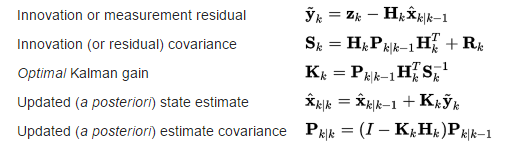  

where $\mathbf{Q}$ and $\mathbf{R}$ are the process noise covariance and measurement noise covariance respectively (covariance of $\mathbf{w}$ and $\mathbf{v}$).

## 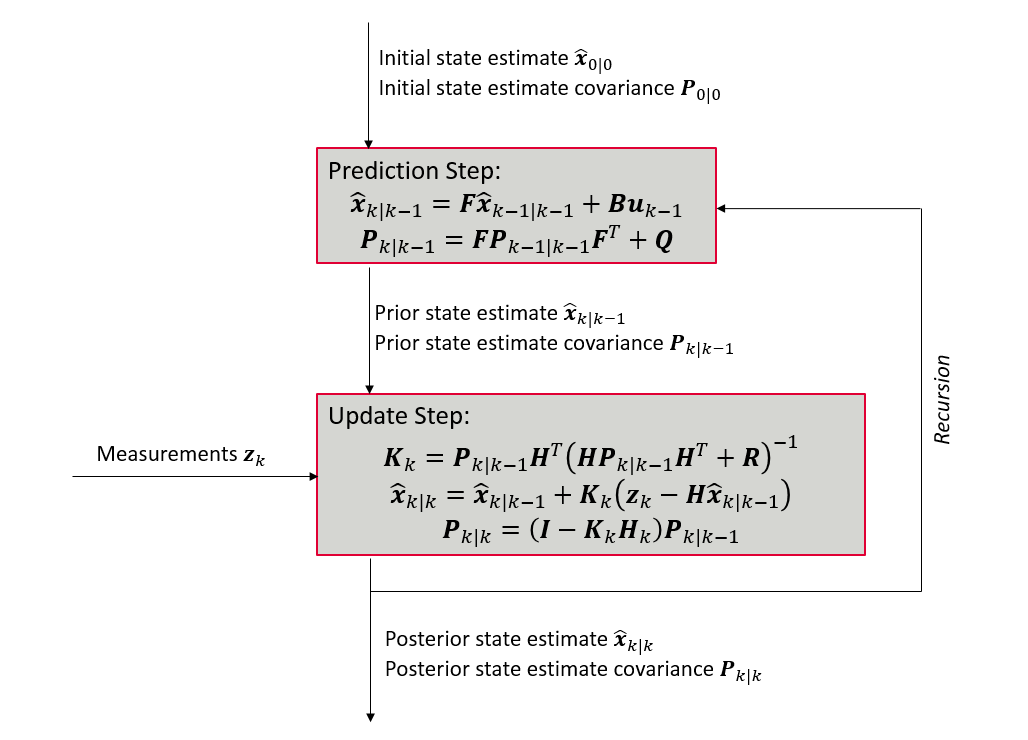

## State Estimation Example: Road Vehicle Sideslip Estimation

***Objective:*** Estimate the sideslip angle $\beta$ at the CoG of a passenger car, using only information available from standard/inexpensive sensors (wheel speeds, steering wheel angle, yaw rate gyroscope and lateral accelerometer).

***Test case:*** 30 km/h slalom manoeuvre simulated using xSim (high fidelity vehicle model). Band-limited Gaussian white-noise added to yaw rate and lateral acceleration channels to simulate real sensors.

***Kalman filter model:***

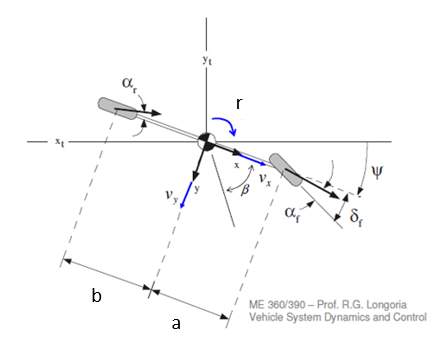


$$\mathbf{x} = 
\left( \matrix{\beta \cr r} \right)$$
      
$$\mathbf{u}
 = \delta_f
$$
        
$$\mathbf{F} = \left( \matrix{ -(C_f+C_r)/v_x & 
-(aC_f-bC_r)/mv_x^2 - 1 \cr
-(aC_f-bC_r)/I_z &
-(a^2C_f+b^2C_r)/I_zv_x
} \right)$$
      
$$\mathbf{B} =\left( \matrix{C_f/mv_x \cr
aC_f/I_z} \right)$$


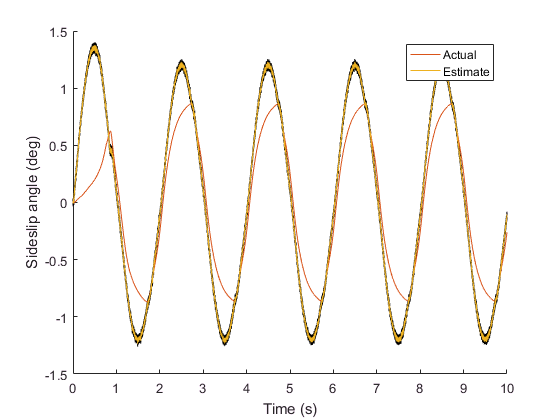

%% KF Example
% Model states are [Sideslip angle, Yaw rate]
% Measurements are [Lateral acceleration, Yaw rate]
% Model inputs are steering angle and longitudinal speed
frictionLevel = 'L'; % Use a "High" friction or "Low" friction test case
KF.Q = diag([1e-3 1e-5]); % Process noise covariance matrix
KF.R = diag([0.00279 1.96e-5]); % Measurement noise covariance matrix
KF.PInit = diag([1e-9 1e-9]); % Initial state estimate covariance matrix
runKF(frictionLevel,KF);

***Model inaccurary on low friction surface:***

Our simple bicycle model in the Kalman filter assumes linear characteristics for the lateral tyre forces:


$$F_{yf} = -C_{\alpha f}\alpha_f \\
F_{yr} = -C_{\alpha r}\alpha_r
$$


This assumption works well when the tyres operate well below the limits of friction. However, when approaching the limits of friction the real force characteristic becomes nonlinear:

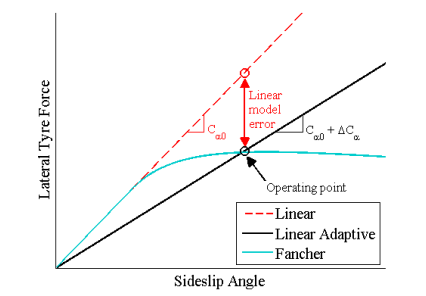

("Fancher" refers to a nonlinear tyre model based on the common brush model)

***Proposed model to deal with low friction:***

Augment the state vector with cornering stiffness "delta" values, so that the model adapts its cornering stiffness estimates on low friction. Effectively now a combined state and parameter estimation problem.


$$\mathbf{x} = 
\left( \matrix{\beta \cr r \cr \Delta C_f \cr \Delta C_r} \right)$$



$$C_f = C_{f0} + \Delta C_f\\

C_r = C_{r0} + \Delta C_r$$


***Problem:*** 

The model is now nonlinear, in the form:

This means we can no longer use the basic Kalman filter.

## Nonlinear Kalman Filtering: Extended Kalman Filter and Unscented Kalman Filter

The EKF is (historically) by far the most common approach to nonlinear Kalman filtering. In a nutshell, the nonlinear model is linearised about the current operating point at each time step and the basic linear Kalman Filter equations are applied to the linearised model. The linearisation involved calculating the following Jacobian matrices for the prediction and measurement parts of the model:

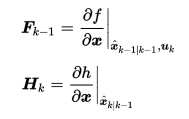

The EKF can perform well in many scenarios, but its linearisation causes it to give poor state estimates (in many cases diverging estimates) if the model in the presence of strong nonlinearities.

The UKF (and variants of) is therefore quickly gaining popularity over the EKF as a nonlinear Kalman filtering method. The UKF is based on the idea that it is "easier to approximate a Gaussian distribution than it is to approximate an arbitrary nonlinear function". Whereas the EKF passes just the prior state estimate and its covariance through a linearisation of the model to obtain the posteriors, the UKF passes a set of several weighted points in the state-space ("sigma points") through the full nonlinear model and determines the posteriors by calculating the mean and covariance of the resulting outputs. In this sense, it bears similarity to particle filters (or sequential Monte Carlo methods). However, its novelty lies in using the "Unscented Transform" to select a minimal set of sigma points. This gives it a substantial computational advantage over particle filters.

Whereas the EKF gives the posterior state estimate and covariance to first order accuracy, the UKF gives at least third order accuracy for any nonlinearity. It also does away with the need to calculate the Jacobians required by the EKF (which often cannot be obtained analytically, and hence add computation time and coding complexity). Since it can be used with any nonlinear state-space model, the UKF is incredibly flexible. There are really very few reasons to ever select the EKF over the UKF.

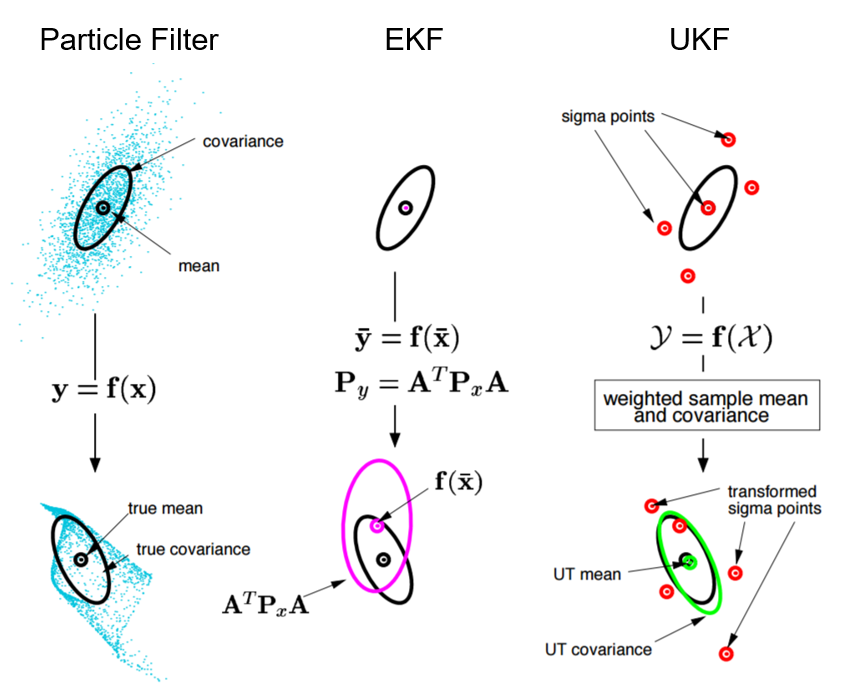

## Example: Combined State and Parameter Estimation With Adaptive Cornering Stiffness

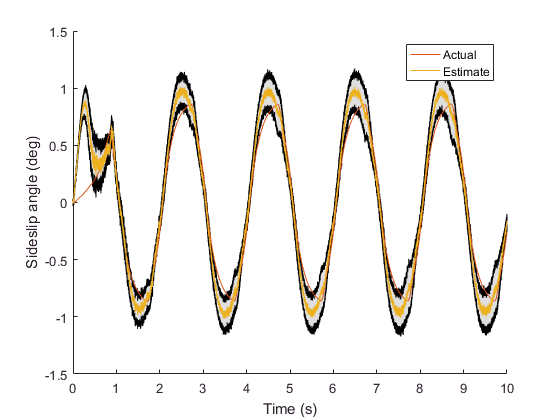

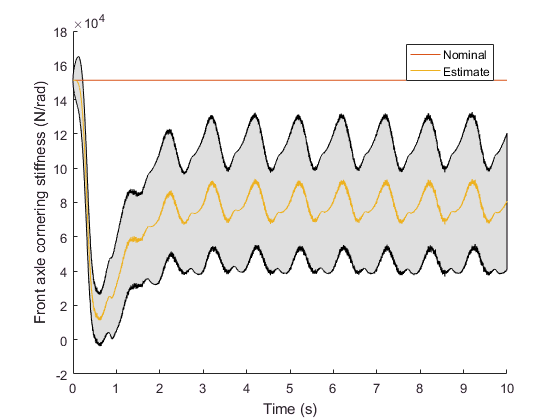

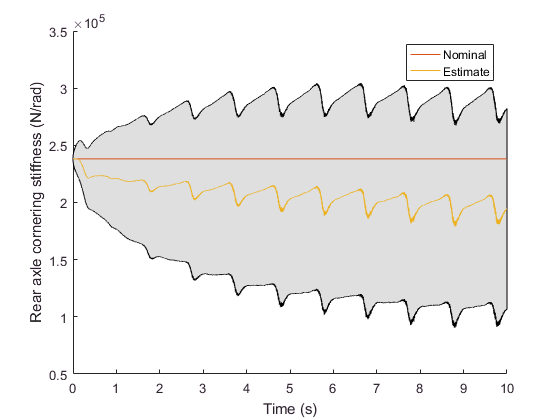

%% UKF Example
% Model states are now [Sideslip angle, Yaw rate, Front cornering stiffness delta, Rear cornering stiffness delta]
% Measurements are [Lateral acceleration, Yaw rate]
% Model inputs are longitudinal speed and steering angle
frictionLevel = 'Low'; % Use a "High" friction or "Low" friction test case
KF.Q = diag([1e-3 1e-5 5e5 5e5]); % Process noise covariance matrix
KF.R = diag([0.00279 1.96e-5]); % Measurement noise covariance matrix
KF.PInit = diag([1e-9 1e-9 1e-9 1e-9]); % Initial state estimate covariance matrix
runUKF(frictionLevel,KF);

## Further improvements: GPS or vision system updates

What if we have measurements of the vehicle's world co-ordinates from a GPS or vision system, but perhaps arriving at a lower rate than the inertial measurements? We can keep a single prediction model but have two or more siwtchable update models. We select the appropriate update model at each time step depending on the new measurements that have arrived.

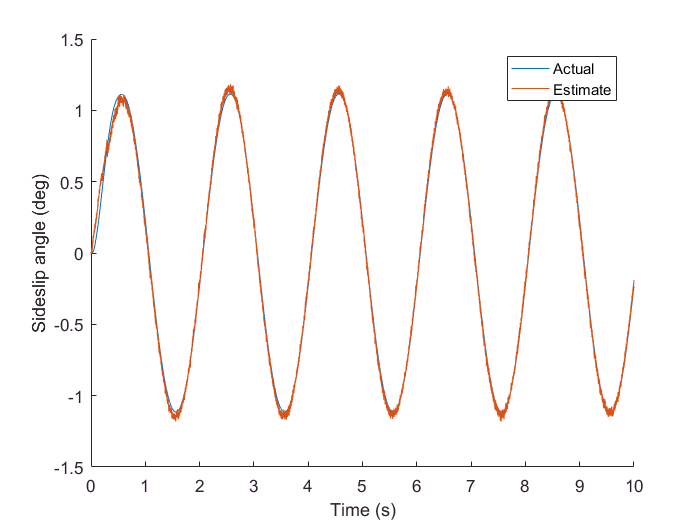

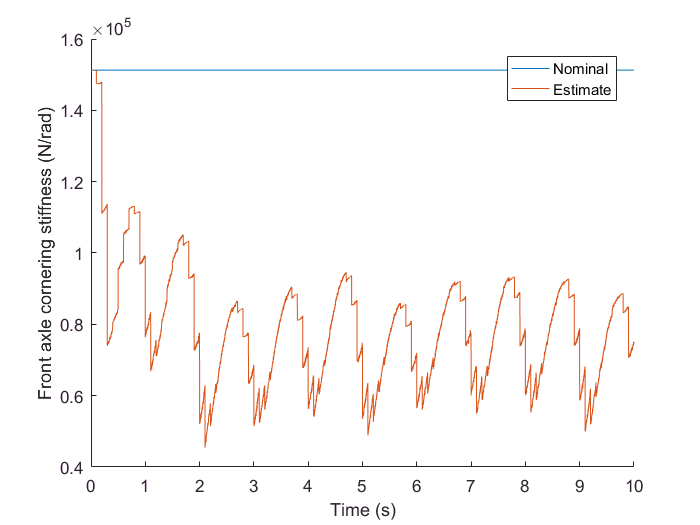

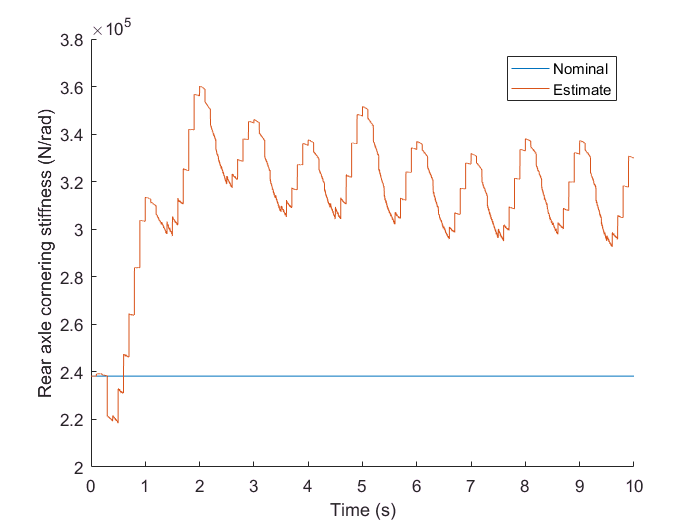

%% UKF Example with GPS position updates
% Model states are now [Sideslip angle, Yaw rate, Heading (yaw) angle, Front cornering stiffness delta, Rear cornering stiffness delta, x World position, y World position]
% Measurements are [Lateral acceleration, Yaw rate, x World position, y World position]
frictionLevel = 'High'; % Use a "High" friction or "Low" friction test case
KF.Q = diag([1e-3 1e-5 1e-12 5e5 5e5 1e-12 1e-12]); % Process noise covariance matrix
KF.R = diag([0.00279 1.96e-5 1e-7 1e-7]); % Measurement noise covariance matrix including position updates (elements will be automatically removed where necessary is a subset of measurements is used)
KF.PInit = diag([1e-9 1e-9 1e-9 1e-9 1e-9 1e-9 1e-9]); % Initial state estimate covariance matrix
KF.dtGPS = 0.1; %GPS update rate (s)
KF.dtIMU = 0.001; %IMU update rate (s)
runUKF2(frictionLevel,KF);

## **Other modelling approaches: Constant acceleration, Forward Integration **

Let's try a couple of pure sensor fusion approaches, getting rid of the vehicle model. Two possible alternatives are compared here:

1) A constant acceleration prediction model which is then updated with IMU and GPS measurements

2) Forward integration of the IMU data as the prediction model, with GPS measurements as updates

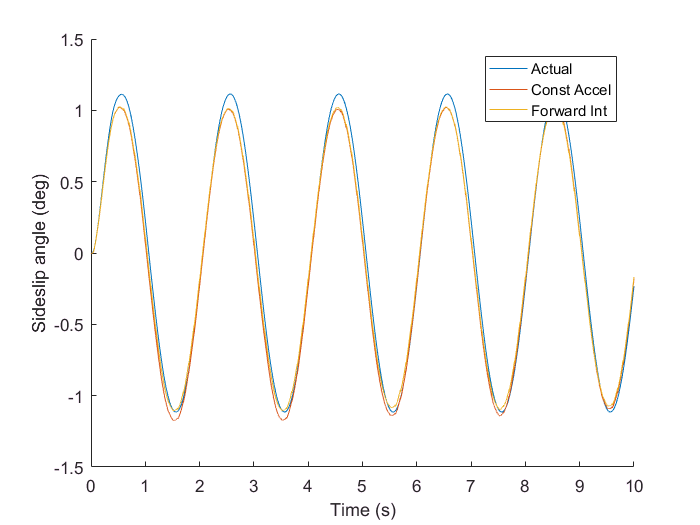

%% UKF Example with with constant acceleration and forward inetgration models
% Model states for UKF3 are [time derivative of longitudinal speed in car frame, longitudinal speed in car frame, world frame x position, time derivative of lateral speed in car frame, lateral speed in car frame, world frame y position, 
% yaw acceleration, yaw rate, heading (yaw) angle]
% Model states for UKF4 are [longitudinal speed in car frame, world frame x position, lateral speed in car frame, world frame y position, heading (yaw) angle]
% Measurements for UKF3 are [longitudinal acceleration, lateral acceleration, yaw rate, world frame x position, world frame y position]
% Measurements for UKF4 are [world frame x position, world frame y position]
% UKF3 has no model inputs
% Model inputs for UKF4 are [longitudinal acceleration, lateral acceleration, yaw rate] 
frictionLevel = 'High'; % Use a "High" friction or "Low" friction test case
KF.Q3 = diag([1e2 1e-10 1e-10 1e2 1e-10 1e-10 1e2 1e-10 1e-10]); % Process noise covariance matrix
KF.Q4 = diag([0.00279*0.001^2 1e-10 0.00279*0.001^2 1e-10 1.96e-5*0.001^2]); % Process noise covariance matrix
KF.R = diag([0.00279 0.00279 1.96e-5 1e-7 1e-7]); % Measurement noise covariance matrix including position updates (elements will be automatically removed where necessary is a subset of measurements is used)
KF.PInit3 = diag([1e-9 1e-9 1e-9 1e-9 1e-9 1e-9 1e-9 1e-9 1e-9]); % Initial state estimate covariance matrix
KF.PInit4 = diag([1e-9 1e-9 1e-9 1e-9 1e-9]); % Initial state estimate covariance matrix
KF.dtGPS = 0.1; %GPS update rate (s)
runUKF3and4(frictionLevel,KF);

## Resources and useful references

1 - Aalto University Matlab Toolbox (recommended for UKF) http://becs.aalto.fi/en/research/bayes/ekfukf/ (includes Kalman smoothers and other KF methods such as Gauss-Hermite Quadrature Kalman Filter, documentation here: http://becs.aalto.fi/en/research/bayes/ekfukf/documentation.pdf)

2 - MAT Kalman Filtering Simulink Library (work in progress... a bit clunky!)

3 - Matlab/Simulink Kalman filter http://uk.mathworks.com/help/ident/ref/kalmanfilter.html?searchHighlight=kalman%20filter (from around R2014a onwards) and Uncented Kalman filter objects (new for R2016b onwards) http://uk.mathworks.com/help/ident/ref/unscentedkalmanfilter.html?searchHighlight=kalman%20filter%20unscented

4 - Original papers on the UKF: https://www.seas.harvard.edu/courses/cs281/papers/unscented.pdf, http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.5.2891&rep=rep1&type=pdf